# Transfer Learning with MATLAB

In this exercise, you will use transfer learning to classify images into 1 of 4 different aircraft categories.

- Delta Wing

- Straight Wing

- Sweptback Wing

- Tapered Wing

This dataset was created from widescale satellite captures of airports. The different aircraft images were cropped from the full satellite images. The low resolution of these images will provide an interesting challenge for the neural network that we will be training.

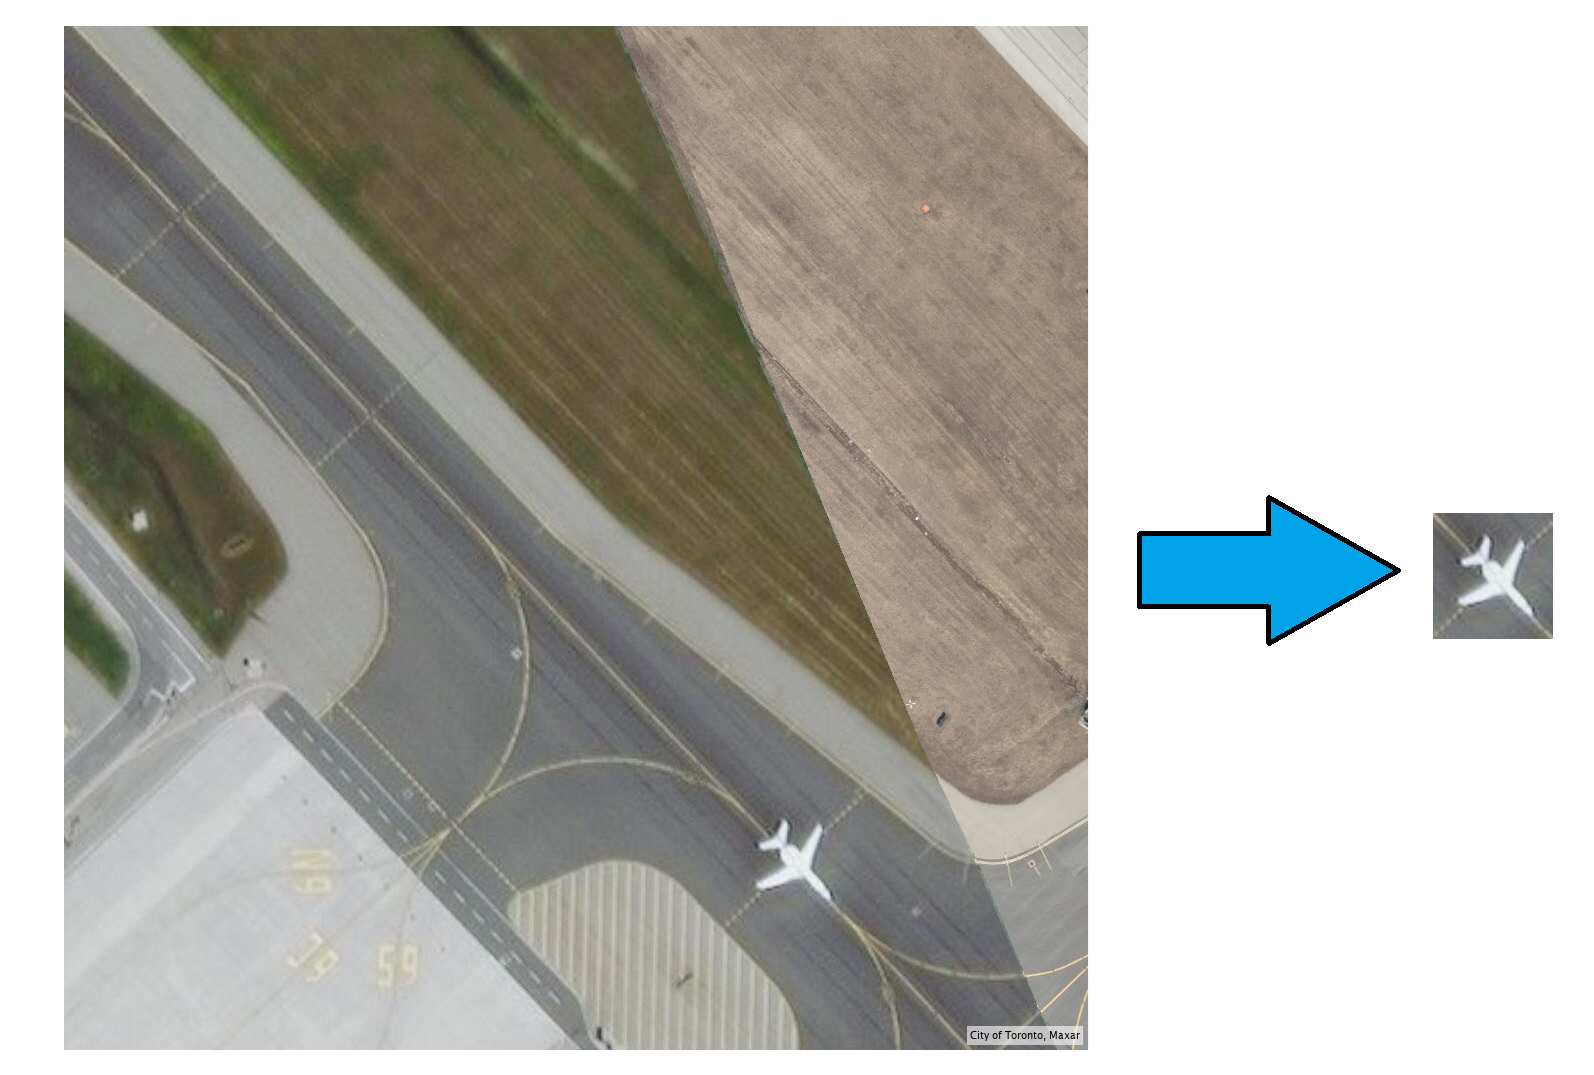

## Unzip data

dirName = fullfile(tempname,'Images');
zipFileName = 'Images.zip';
% Unzip the file if the directory does not exist or is empty
if ~isfolder(dirName) || isempty(dir(dirName))
    unzip(zipFileName, dirName);
    disp('Unzipped Images.zip successfully.');
else
    disp('Directory "Images" already exists and contains files.');
end

Unzipped Images.zip successfully.


## Create a datastore

[Datastores](https://www.mathworks.com/help/matlab/datastore.html) allow you to reference collections of data that may be too large to fit in memory. A datastore allows you to read and process data stored in multiple files on a disk, a remote location, or a database. With image datastores, you can also label images, set a custom read function and split images into different sets. 

Create a datastore, including subdirectories and add labels based on the filenames. Then, get a feel for the dataset by viewing some of the sample images and their ground truth labels.

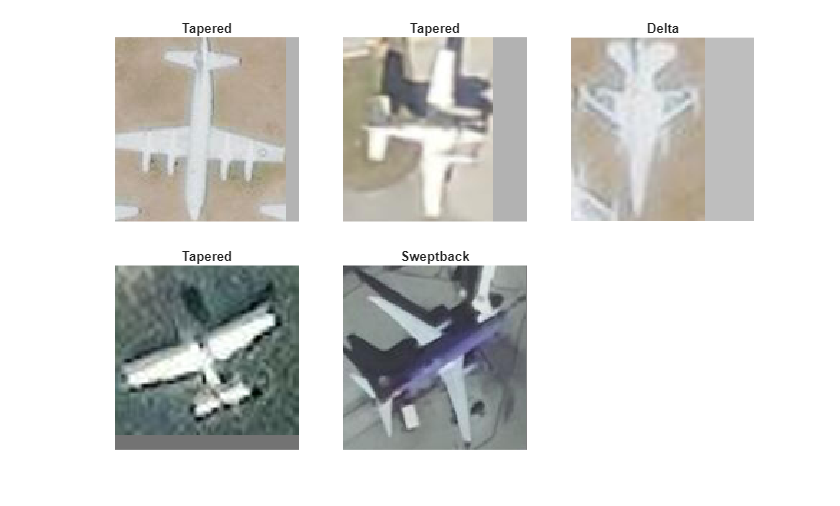

imds = imageDatastore(dirName,...  
    IncludeSubfolders=true, ...
    LabelSource="foldernames"); 

numToDisplay = 5;

displayImages(imds, numToDisplay);

## Look at the spread of our dataset

Let's look at the different output classes and the number of observations in each class. Slight class imbalance is okay. However, if we had significant class imbalance, we would look into correction techniques such as oversampling some of the data or modifying the network to account for the natural imbalance of real-world occurrences. 

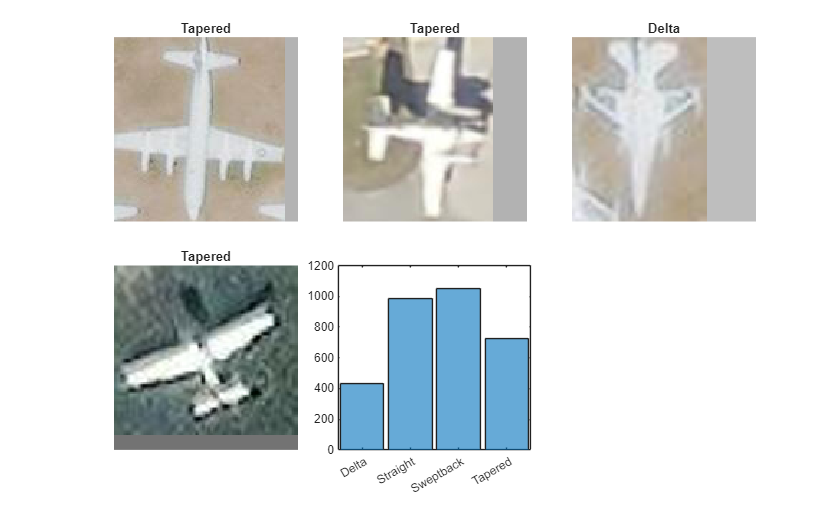

histogram(imds.Labels)

numObj = countEachLabel(imds)

numObj = 4×2 table
      Label      Count
    _________    _____
    Delta         433 
    Straight      987 
    Sweptback    1053 
    Tapered       728 

## Gather class names and number of classes

We will need this information when performing transfer learning later in this exercise.

classNames = categories(imds.Labels)

classNames = 4×1 cell array
    {'Delta'    }
    {'Straight' }
    {'Sweptback'}
    {'Tapered'  }

numClasses = numel(classNames)

numClasses = 4

## Perform inference using pretrained network

Pass an image through a [pretrained network](https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html), GoogleNet. You can run this section multiple times to read the next image in the datastore. 

Based on the results, can we use this network as-is?

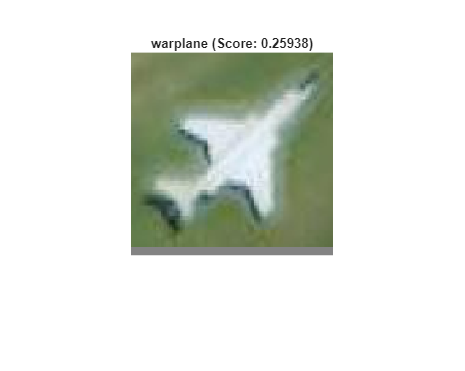

[net, googlenetClasses] = imagePretrainedNetwork("googlenet");
im = read(imds);
figure
imshow(im)
X = single(im);
scores = predict(net, X);
[label, score] = scores2label(scores, googlenetClasses);
title(string(label) + " (Score: " + score + ")")

The score of the prediction is the likeliness that the image belongs to the given class. The scores across all classes add up to 1. 

## View network architecture

Let's view the network in the [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html). Using the Deep Network Designer, find the fully connected layer named "loss3-classifier" towards the bottom of the graph. 

Based on the OutputSize property of this layer, how many different classes is the original network trained on?

deepNetworkDesigner(net)

% TODO: How many classes is the original network trained on?

## Modify the network layers

We will need to modify the network layers so that we can retrain the network on our set of 4 different aircraft types. The imagePretrainedNetwork function will do this automatically if we specify the appropriate input arguments.

`net = imagePretrainedNetwork("network-name-placeholder", NumClasses = numClassesPlaceholder)`

% TODO: Call imagePretrainedNetwork to modify the "googlenet" layers to
% have 4 classes. Replace the placeholders below.

% net = imagePretrainedNetwork("network-name-placeholder", NumClasses = numClassesPlaceholder)
net = imagePretrainedNetwork("googlenet", NumClasses=numClasses)

net =   dlnetwork with properties:

         Layers: [143×1 nnet.cnn.layer.Layer]
    Connections: [169×2 table]
     Learnables: [116×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1
  View summary with summary.

## Splitting image datastore into 3 sets:  | Train | Validate | Test |

It is a best practice to split our data into a training, validation and test set.

- Training - used to train our network by establishing proper weights that allow for accurate classification

- Validation - a dataset that you test the network on during or after training. If the results are poor, retrain the network with different hyperparameters and/or network architecture

- Test - an unseen dataset that is used as an unbiased measurement of network accuracy. Use this after you are happy with your validation performance.

A common ratio is a 70/15/15 split. Use the [splitEachLabel](https://www.mathworks.com/help/matlab/ref/datastore.spliteachlabel.html) function to split your datastore into the three desired sets.

[imdsTrain,imdsValidation,imdsTest] = splitEachLabel(imds,0.7,0.15,"randomized");

## Freeze original layers

To speed up training time, freeze the weights of the original network layers.

[layerName,learnableNames] = networkHead(net)

layerName = "loss3-classifier"

learnableNames = 2×1 string array
    "loss3-classifier/Weights"
    "loss3-classifier/Bias"

net = freezeNetwork(net,LayerNamesToIgnore=layerName);

## Specify training options

[Training options](https://www.mathworks.com/help/deeplearning/ug/setting-up-parameters-and-training-of-a-convnet.html), also known as hyperparameters, tell our network how to run the training.

In this section, we will change **Max epochs** which controls how many times we pass our training images through the network during training.

**TO DO: Set Training Options for the network  **

- `Set maxEpochs equal to 30`

% TODO set maxEpochs equal to 30
maxEpochs = 30;

options = trainingOptions("adam", ...
    ValidationData=imdsValidation, ...
    ValidationFrequency=10, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false, ...
    MaxEpochs=maxEpochs, ...
    InitialLearnRate=0.0005, ...
    MiniBatchSize=256);

## Train neural network

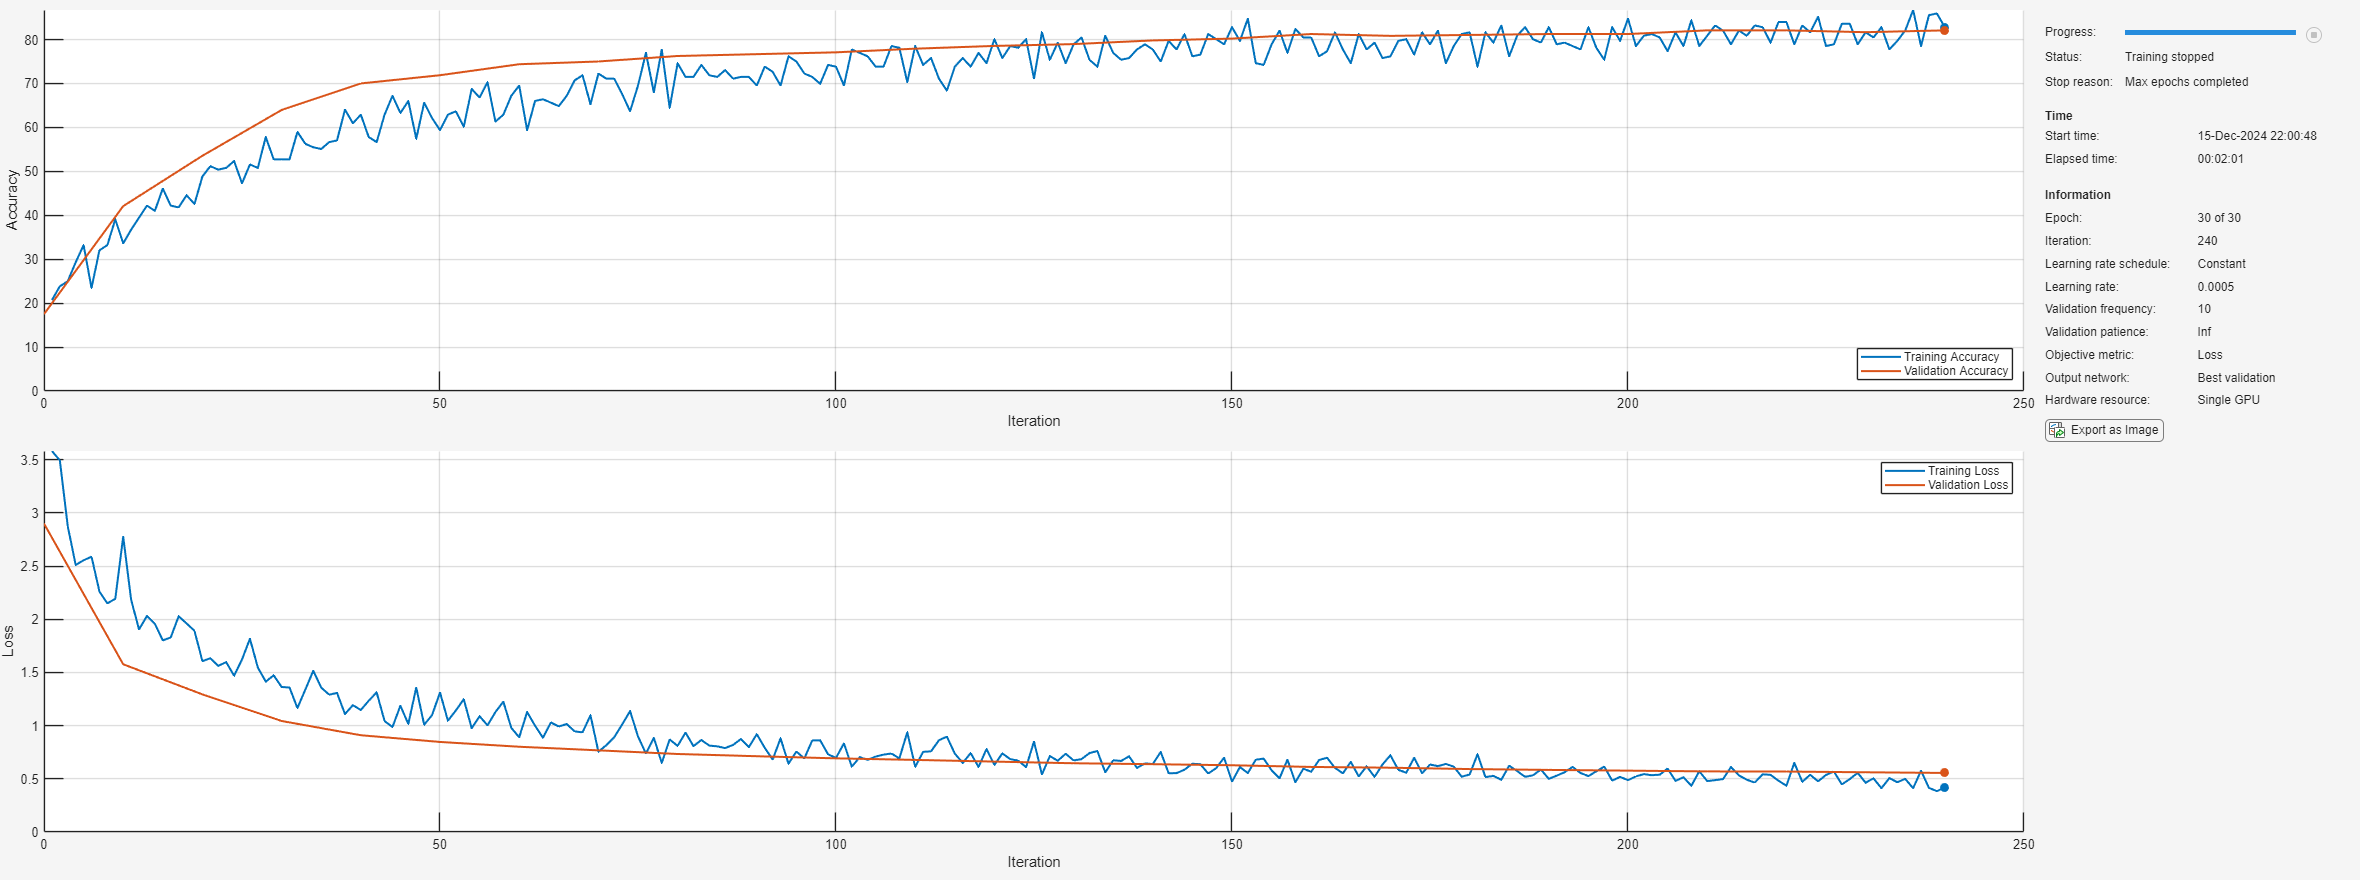

net = trainnet(imdsTrain,net,"crossentropy",options);

## Test neural network

Evaluate the network  using the test dataset that was held out.

YTest = minibatchpredict(net,imdsTest);
YTest = scores2label(YTest,classNames);

Visualize the classification accuracy in a confusion chart.

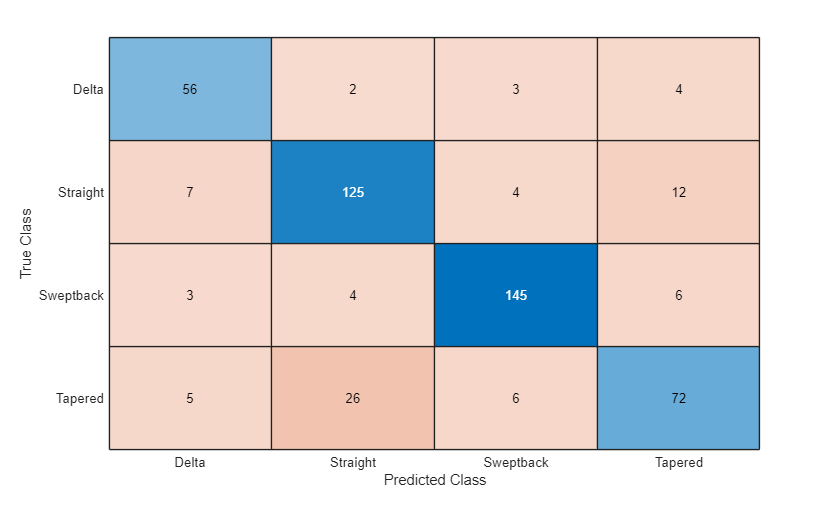

TTest = imdsTest.Labels;
figure
confusionchart(TTest,YTest);

Evaluate the classification accuracy for the test data. The accuracy is the percentage of correct predictions.

acc = mean(TTest==YTest)

acc = 0.8292

## Make predictions with new data

Classify an image with the retrained network.

[img, info] = read(imdsTest);
label = info.Label;
scores = minibatchpredict(net,img);
[pred,score] = scores2label(scores,classNames);

Display the image with the predicted label and the corresponding score.

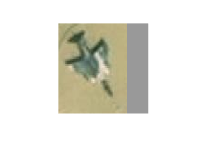

figure
imshow(img)
title(["Predicted: " + string(pred) + ", Actual: " + string(label)+ " (" + gather(score) + ")"])

## Helper Functions

function displayImages(imds, numToDisplay)

tiledlayout('flow', 'TileSpacing', 'Compact');

for ii=1:numToDisplay
    nexttile
    
    % Generate random number < # of total images
    randNum = randi(length(imds.Files));
    
    % Read random image from the datastore and visualize
    [imTemp,info] = readimage(imds,randNum);
    imshow(imTemp)
    title(char(info.Label),'Interpreter','none')
end

end

*Copyright 2024 The MathWorks, Inc.*